# Market Modeling Simulation #1

# Naive Estimation of the Noise (Sample Estimators)

**1. Javier Chacón, 2. Tatiana Gelvez, 3. Henry Arguello**

These simulations are the initial work on market modeling of our proyect, first, for we to have a general view of the issues that concerns the estimation of the noise, we will use sample estimators to make some analysis over the market data. The estimators we are going to use are:

- Sample mean of the signal.

- Sample variance of the noise.

- Mean absolute deviation.

- Interquartile range.

The model we are trying to fit with with the data is given by,

$\mathbf{r}_t = \mathbf{\mu}_t + \mathbf{w}_t$,

where $\mathbf{\mu}_t$ is the conditional mean

$\mathbf{\mu}_t = E[\mathbf{r}_t | F_{t-1}]$,

and $\mathbf{w}_t$ is a white noise with zero mean and conditional variance

$\sum{_t} = E[(\mathbf{r}_t - \mathbf{\mu}_t)(\mathbf{r}_t - \mathbf{\mu}_t)^T|F_{t-1}]$,

let us show some code examples.

%Data adquisition from the Yahoo financial API
disp('Request historical S&P 500 price');

Request historical S&P 500 price


initDate = '10-May-2009';
endDate = '10-May-2019';
symbol = '^GSPC';
interval = '1d';
gspc10Y = getMData(symbol, initDate, endDate, interval);


For this initial show we used the daily data of the S&P500 index over the las 10 years, Now we are going to calculate the log-returns from the close price series.

cP = gspc10Y.Close';
s1 = size(cP, 2);
logRet = zeros(1, s1 - 1);
Ret = zeros(1, s1 - 1);
logPri = zeros(1, s1 - 1);
for i = 2:s1
    logRet(1, i-1) = log(cP(1, i)) - log(cP(1, i-1));
    Ret(1, i-1) = (cP(1, i) - cP(1, i-1))/cP(1, i-1);
    logPri(1, i-1) = log(cP(1, i));
end

Now we can take a look at the data. Here we are going to decompose the original signal in two different ways, first into a mean component and a noise component, and second using a least squares trend line instead of the sample mean, and a noise component. 

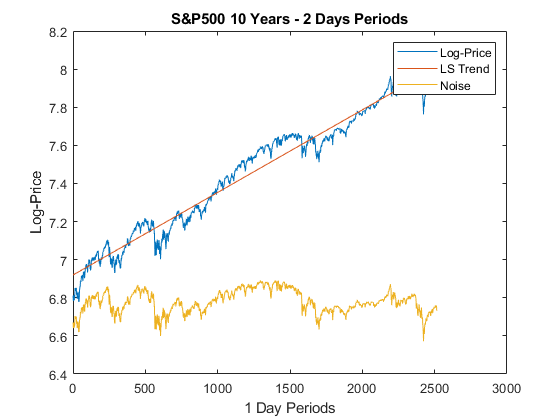

%Days arrays
x1 = 1:(s1-1)/2;
x2 = 1:s1-1;
%First look at the log-prices and first decomposition
plot(x2, logPri)
hold on
%Calculation of the least squares trend line
[b, a] = leastS(x2, logPri);
priTrend = a*x2 + b;
priNoise = (logPri - priTrend) + min(logPri);
plot(x2, priTrend)
plot(x2, priNoise)
legend({'Log-Price', 'LS Trend', 'Noise'})
title('S&P500 10 Years - 2 Days Periods')
xlabel('1 Day Periods')
ylabel('Log-Price')
hold off

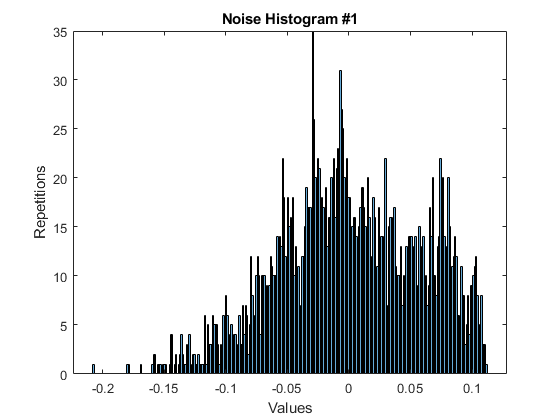

%Plot of the noise histogram for the first look
priNoise = priNoise - mean(priNoise);
histogram(priNoise, 300)
title('Noise Histogram #1')
xlabel('Values')
ylabel('Repetitions')

%Calculation of the sample mean over short periods of 2 days
meanAr = zeros(1, (s1-1)/2);
r1 = zeros(1, (s1-1)/2);
lr2 = zeros(1, (s1-1)/2);
varN = zeros(1, (s1-1)/2);
madAr = zeros(1, (s1-1)/2);
iqrAr = zeros(1, (s1-1)/2);
j = 1;
for i = 2:2:(s1-1)
    lr2(1, j) = logRet(1, i);
    meanAr(1, j) = mean([logRet(1, i-1), logRet(1, i)]);
    d2dAr1 = logRet(1, i-1) - meanAr(1, j);
    d2dAr2 = logRet(1, i) - meanAr(1, j);
    varN(1, j) = var([d2dAr1, d2dAr2]);
    madAr(1, j) = mad([d2dAr1, d2dAr2]);
    iqrAr(1, j) = iqr([d2dAr1, d2dAr2]);
    j = j + 1;
end
noi1 = lr2 - meanAr;
gpdf = normpdf(meanAr);

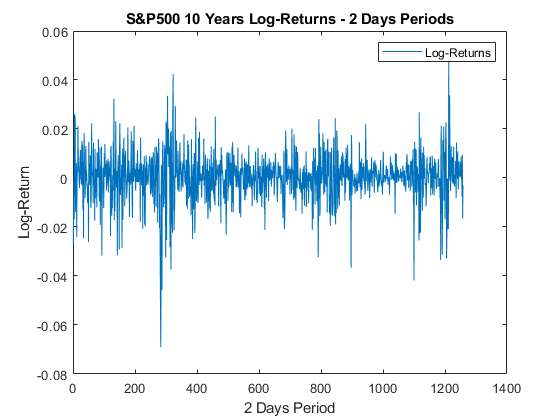

plot(x1, lr2)
legend({'Log-Returns'})
title('S&P500 10 Years Log-Returns - 2 Days Periods')
xlabel('2 Days Period')
ylabel('Log-Return')

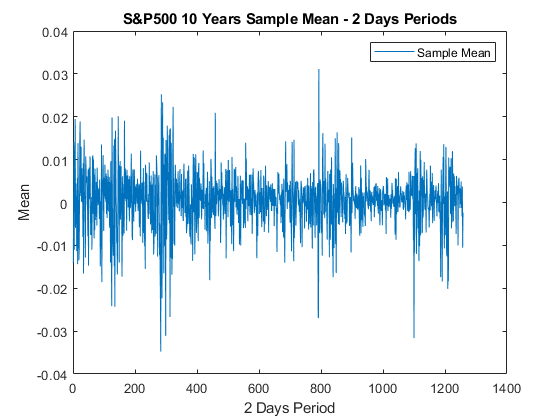

plot(x1, meanAr)
legend({'Sample Mean'})
title('S&P500 10 Years Sample Mean - 2 Days Periods')
xlabel('2 Days Period')
ylabel('Mean')

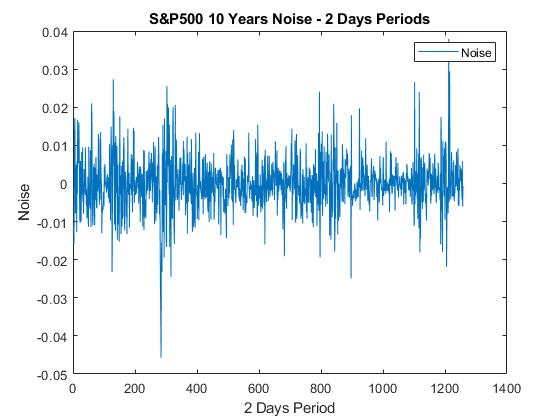

plot(x1, noi1)
legend({'Noise'})
title('S&P500 10 Years Noise - 2 Days Periods')
xlabel('2 Days Period')
ylabel('Noise')

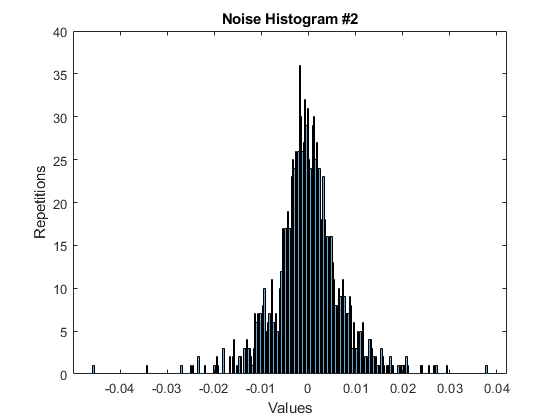

h1 = histogram(noi1, 300);
title('Noise Histogram #2')
xlabel('Values')
ylabel('Repetitions')

As we can clearly see we may achieve a much better aproximation using the log-returns as meassure of market behavior.

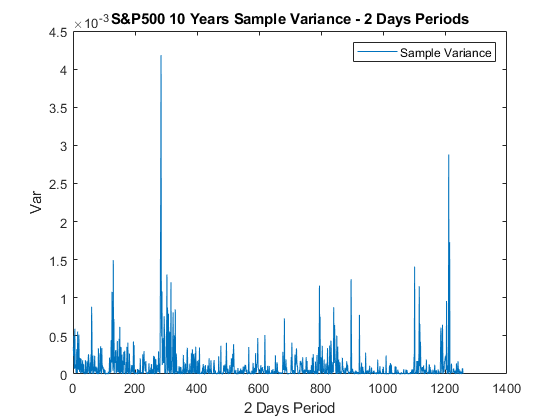

plot(x1, varN)
legend({'Sample Variance'})
title('S&P500 10 Years Sample Variance - 2 Days Periods')
xlabel('2 Days Period')
ylabel('Var')

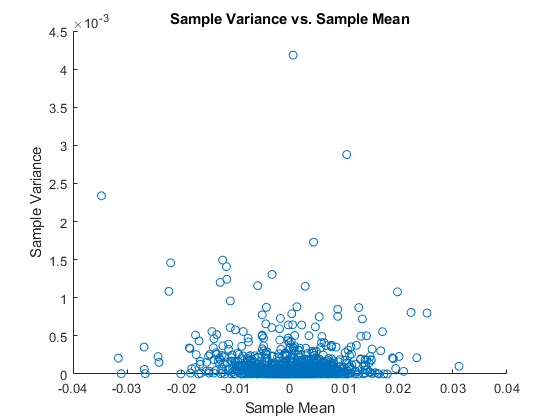

scatter(meanAr, varN)
title('Sample Variance vs. Sample Mean')
xlabel('Sample Mean')
ylabel('Sample Variance')

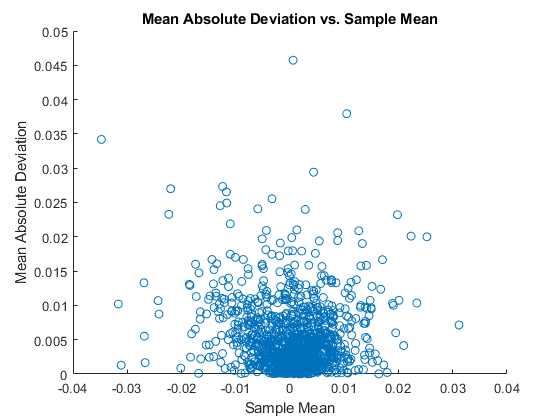

scatter(meanAr, madAr)
title('Mean Absolute Deviation vs. Sample Mean')
xlabel('Sample Mean')
ylabel('Mean Absolute Deviation')

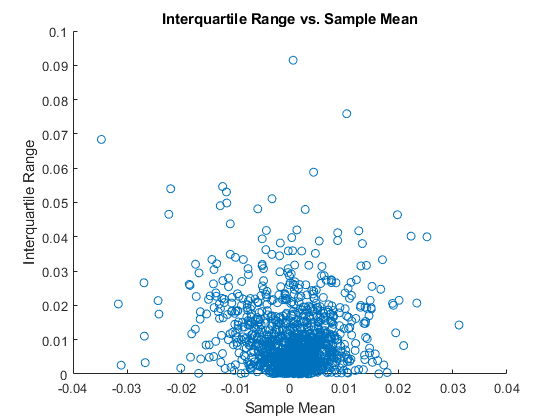

scatter(meanAr, iqrAr)
title('Interquartile Range vs. Sample Mean')
xlabel('Sample Mean')
ylabel('Interquartile Range')

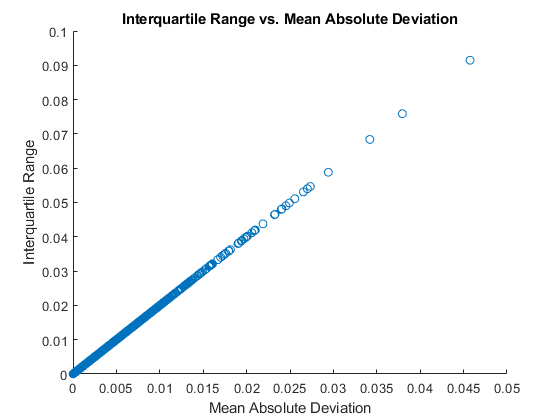

scatter(madAr, iqrAr)
title('Interquartile Range vs. Mean Absolute Deviation')
xlabel('Mean Absolute Deviation')
ylabel('Interquartile Range')

%Calculation of the sample mean over periods of 25 days
s1 = 2500;
s2 = 25;
logRet = logRet(1, 1:s1);
meanAr = zeros(1, s1/s2);
r1 = zeros(1, s1/s2);
lr2 = zeros(1, s1/s2);
varN = zeros(1, s1/s2);
madAr = zeros(1, s1/s2);
iqrAr = zeros(1, s1/s2);
j = 1;
for i = s2:s2:s1
    lr2(1, j) = logRet(1, i);
    meanAr(1, j) = mean(logRet(1, i-s2+1:i));
    d2dAr1 = logRet(1, i-s2+1) - meanAr(1, j);
    d2dAr2 = logRet(1, i) - meanAr(1, j);
    varN(1, j) = var(logRet(1, i-s2+1:i));
    madAr(1, j) = mad(logRet(1, i-s2+1:i));
    iqrAr(1, j) = iqr(logRet(1, i-s2+1:i));
    j = j + 1;
end
noi1 = lr2 - meanAr;
gpdf = normpdf(meanAr);
x1 = 1:s1/s2;

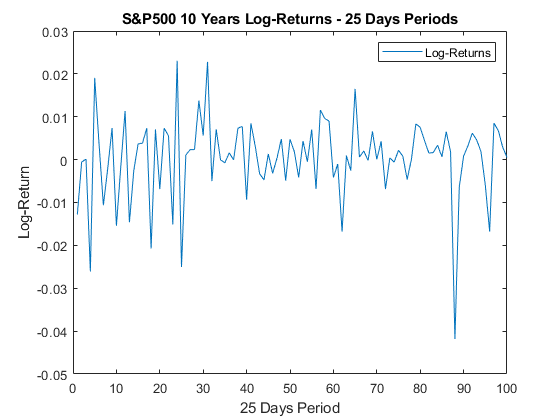

plot(x1, lr2)
legend({'Log-Returns'})
title('S&P500 10 Years Log-Returns - 25 Days Periods')
xlabel('25 Days Period')
ylabel('Log-Return')

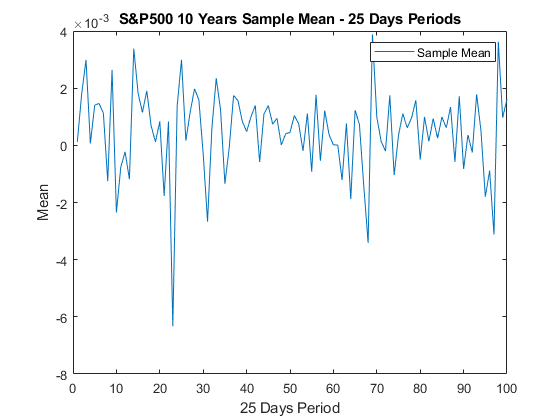

plot(x1, meanAr)
legend({'Sample Mean'})
title('S&P500 10 Years Sample Mean - 25 Days Periods')
xlabel('25 Days Period')
ylabel('Mean')

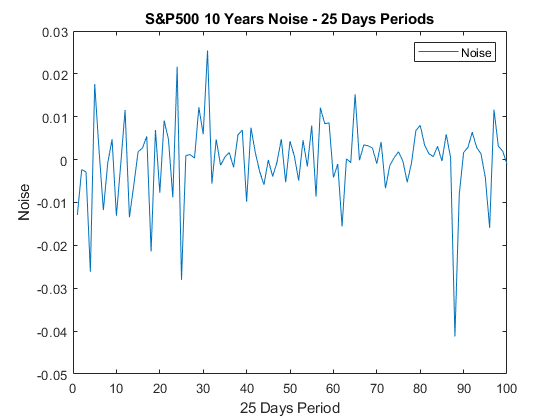

plot(x1, noi1)
legend({'Noise'})
title('S&P500 10 Years Noise - 25 Days Periods')
xlabel('25 Days Period')
ylabel('Noise')

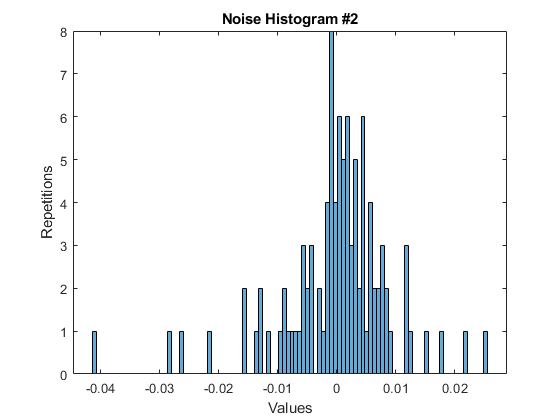

h1 = histogram(noi1, 100);
title('Noise Histogram #2')
xlabel('Values')
ylabel('Repetitions')

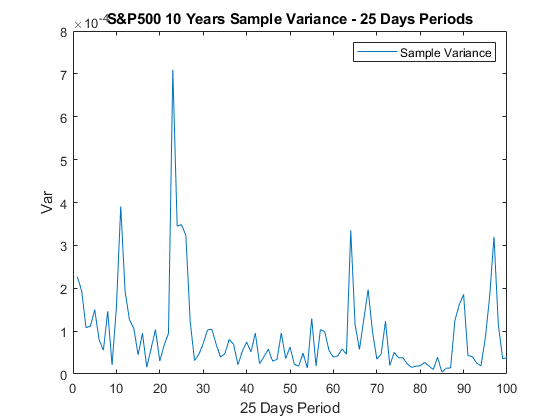

plot(x1, varN)
legend({'Sample Variance'})
title('S&P500 10 Years Sample Variance - 25 Days Periods')
xlabel('25 Days Period')
ylabel('Var')

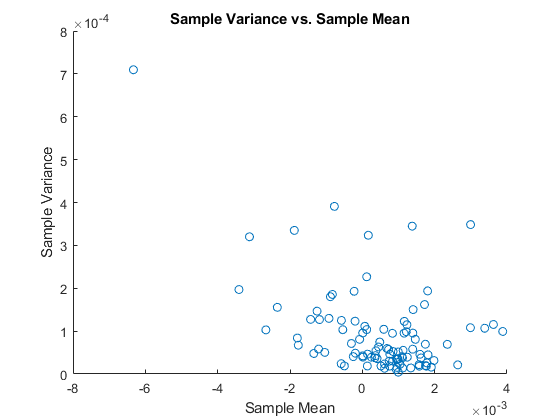

scatter(meanAr, varN)
title('Sample Variance vs. Sample Mean')
xlabel('Sample Mean')
ylabel('Sample Variance')

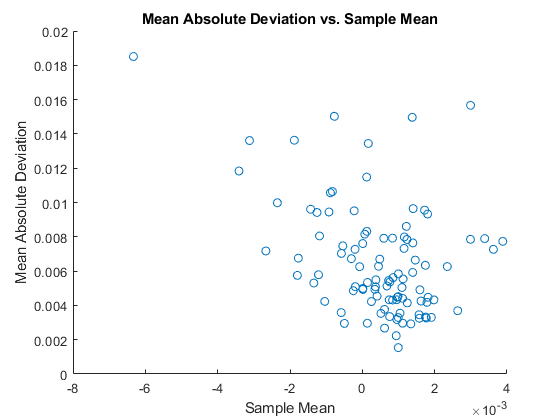

scatter(meanAr, madAr)
title('Mean Absolute Deviation vs. Sample Mean')
xlabel('Sample Mean')
ylabel('Mean Absolute Deviation')

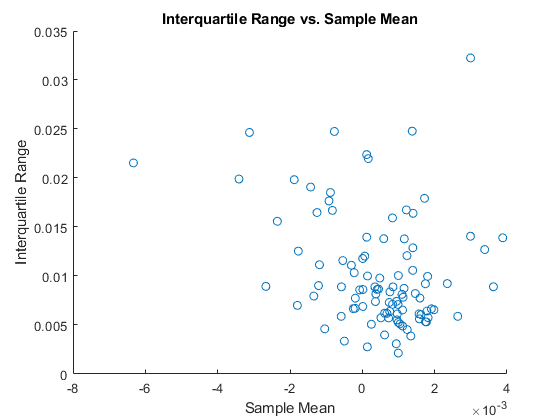

scatter(meanAr, iqrAr)
title('Interquartile Range vs. Sample Mean')
xlabel('Sample Mean')
ylabel('Interquartile Range')

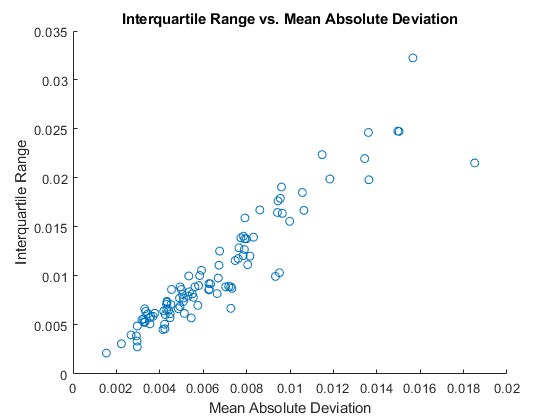

scatter(madAr, iqrAr)
title('Interquartile Range vs. Mean Absolute Deviation')
xlabel('Mean Absolute Deviation')
ylabel('Interquartile Range')

%Calculation of the sample mean over periods of 5 days
s1 = 2500;
s2 = 5;
logRet = logRet(1, 1:s1);
meanAr = zeros(1, s1/s2);
r1 = zeros(1, s1/s2);
lr2 = zeros(1, s1/s2);
varN = zeros(1, s1/s2);
madAr = zeros(1, s1/s2);
iqrAr = zeros(1, s1/s2);
j = 1;
for i = s2:s2:s1
    lr2(1, j) = logRet(1, i);
    meanAr(1, j) = mean(logRet(1, i-s2+1:i));
    d2dAr1 = logRet(1, i-s2+1) - meanAr(1, j);
    d2dAr2 = logRet(1, i) - meanAr(1, j);
    varN(1, j) = var(logRet(1, i-s2+1:i));
    madAr(1, j) = mad(logRet(1, i-s2+1:i));
    iqrAr(1, j) = iqr(logRet(1, i-s2+1:i));
    j = j + 1;
end
noi1 = lr2 - meanAr;
gpdf = normpdf(meanAr);
x1 = 1:s1/s2;

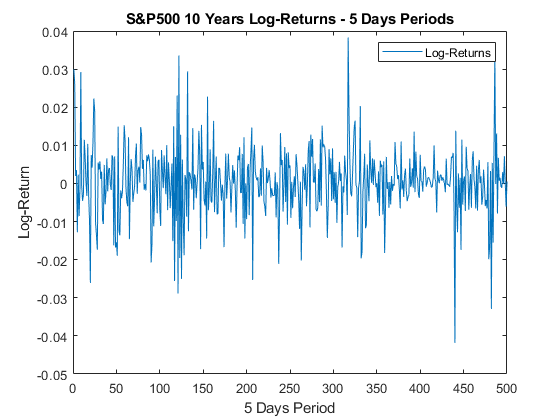

plot(x1, lr2)
legend({'Log-Returns'})
title('S&P500 10 Years Log-Returns - 5 Days Periods')
xlabel('5 Days Period')
ylabel('Log-Return')

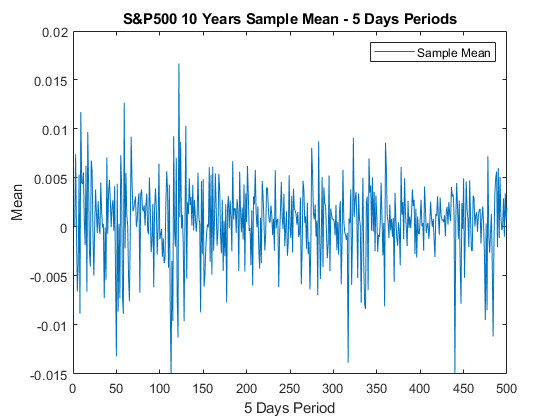

plot(x1, meanAr)
legend({'Sample Mean'})
title('S&P500 10 Years Sample Mean - 5 Days Periods')
xlabel('5 Days Period')
ylabel('Mean')

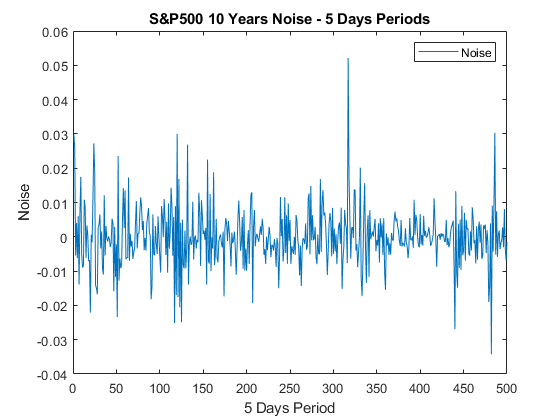

plot(x1, noi1)
legend({'Noise'})
title('S&P500 10 Years Noise - 5 Days Periods')
xlabel('5 Days Period')
ylabel('Noise')

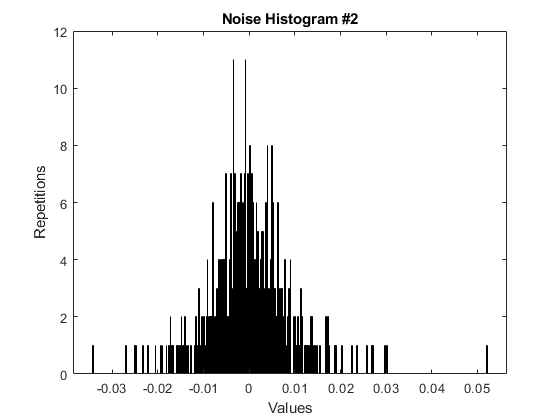

h1 = histogram(noi1, 500);
title('Noise Histogram #2')
xlabel('Values')
ylabel('Repetitions')

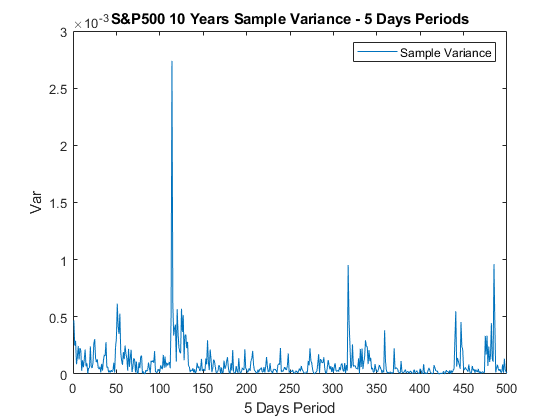

plot(x1, varN)
legend({'Sample Variance'})
title('S&P500 10 Years Sample Variance - 5 Days Periods')
xlabel('5 Days Period')
ylabel('Var')

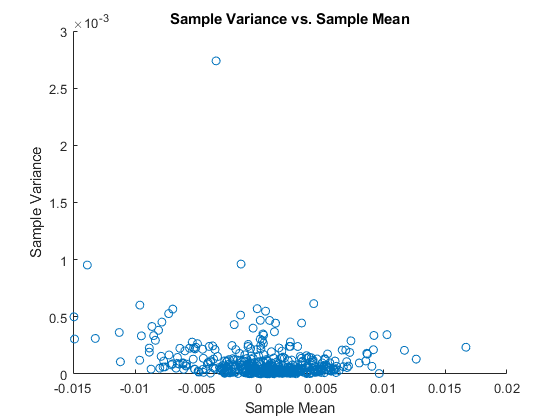

scatter(meanAr, varN)
title('Sample Variance vs. Sample Mean')
xlabel('Sample Mean')
ylabel('Sample Variance')

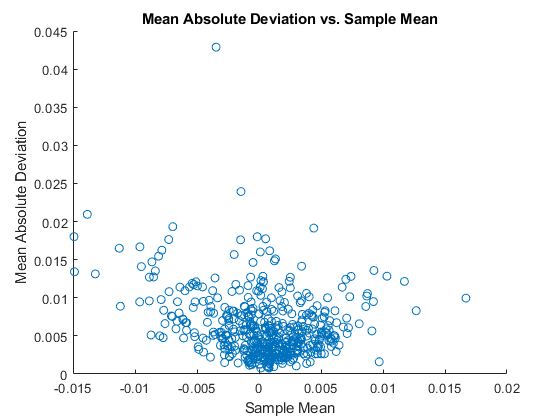

scatter(meanAr, madAr)
title('Mean Absolute Deviation vs. Sample Mean')
xlabel('Sample Mean')
ylabel('Mean Absolute Deviation')

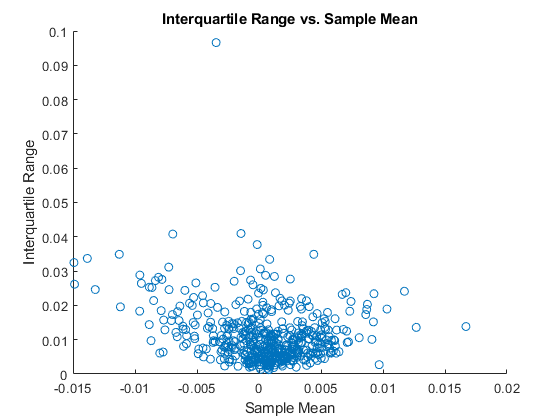

scatter(meanAr, iqrAr)
title('Interquartile Range vs. Sample Mean')
xlabel('Sample Mean')
ylabel('Interquartile Range')

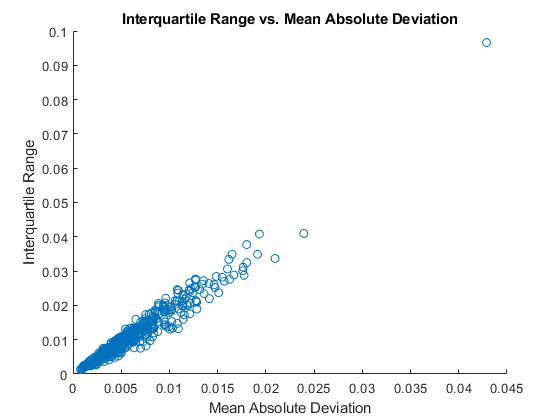

scatter(madAr, iqrAr)
title('Interquartile Range vs. Mean Absolute Deviation')
xlabel('Mean Absolute Deviation')
ylabel('Interquartile Range')